# **Résultats simulation Monte-Carlo**

Monte-Carlo avec un nombre d'essais égal à :  

M = sprintf('%0.2g',N)

M = '1e+05'

## Loi suivie par les variables aléatoires et leur distribution

Les distributions des différentes variables aléatoires sont explicitées ci-dessous : 

loi_a_bino_px

loi_a_bino_px = 'uniforme'

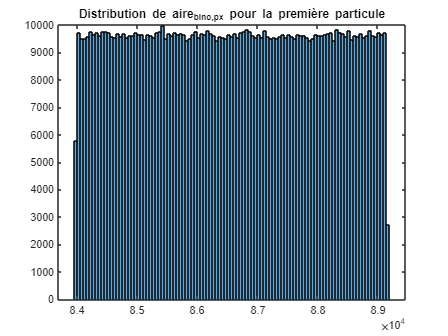

figure(1);
histogram(A_bino_px(1,:));
title('Distribution de aire_{bino,px} pour la première particule');


loi_L_ref

loi_L_ref = 'uniforme'

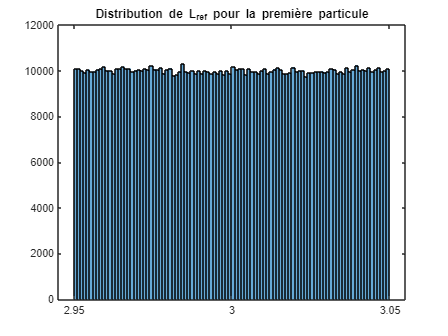

figure(2);
histogram(L_ref(1,:));
title('Distribution de L_{ref} pour la première particule');


loi_n_px

loi_n_px = 'uniforme'

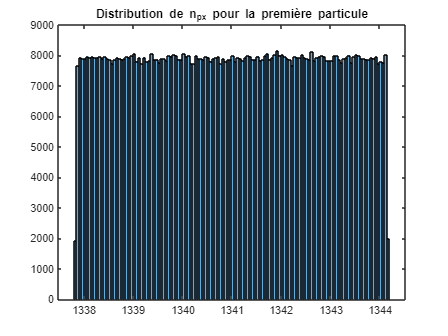

figure(3);
histogram(n_px(1,:));
title('Distribution de n_{px} pour la première particule');


loi_uvp_px

loi_uvp_px = 'normale'

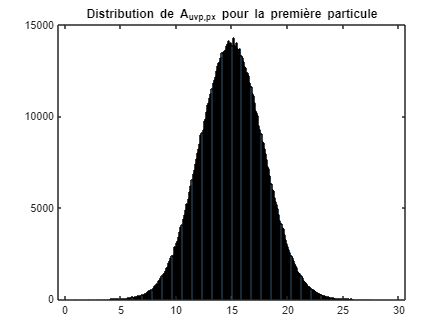

figure(4);
histogram(A_uvp_px(1,:));
title('Distribution de A_{uvp,px} pour la première particule');

## Type de régression utilisée

switch modele_regression
    case 'A'
        disp('Le modèle de régression est de type puissance.');
        disp('La variable explicative (X) est l aire qui provient de la mesure en pixel par l UVP (X = A_uvp_px).');
        disp('La variable à expliquer (Y) est l aire provenant de la mesure effectuée avec le microscope binoculaire (Y = A_bino_mm_2)')
    case 'B'
       disp('Le modèle de régression est de type puissance. ');       
       disp('La variable explicative (X) est l aire qui provient de la mesure par le microscope binoculaire (X = A_bino_mm_2).');
       disp('La variable à expliquer (Y) est l aire qui provient de la mesure en pixel par l UVP (Y = A_uvp_px)');   
end

Le modèle de régression est de type puissance.


La variable explicative (X) est l aire qui provient de la mesure en pixel par l UVP (X = A_uvp_px).


La variable à expliquer (Y) est l aire provenant de la mesure effectuée avec le microscope binoculaire (Y = A_bino_mm_2)


## Histogramme de distribution de  Aa et exp

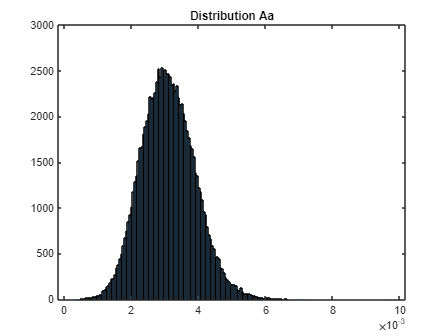

%% histogramme de fréquence pour Aa et exp
figure(5);
histogram(Aa);
title('Distribution Aa')

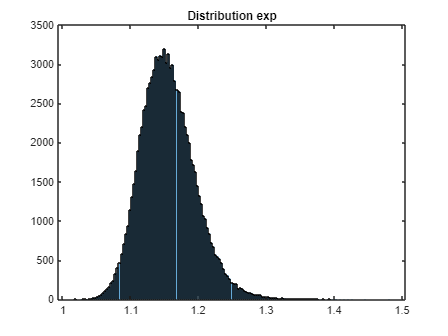


figure(6);
histogram(expo);
title('Distribution exp')

## Résultats 

- R²

moy_R = mean(Radjusted);
min_R = min(Radjusted);
max_R = max(Radjusted);
R = table('Size',[1 3], 'VariableTypes',{'double', 'double','double'},'RowNames', {'R² ajusté'},'VariableNames', {'valeur moyenne','min','max'});
R(1,:)={moy_R,min_R,max_R}

R = 1×3 table
                 valeur moyenne    min       max  
                 ______________    ____    _______

    R² ajusté         -Inf         -Inf    0.99613


- Aa


q_alpha = 1.96;
moy_Aa = mean(Aa);
s_Aa = sqrt(mean((Aa-moy_Aa).^2));

I_Aa = [moy_Aa - q_alpha * s_Aa / sqrt(length(Aa)) ; moy_Aa + q_alpha * s_Aa / sqrt(length(Aa))] ; 

coeff_Aa = table('Size',[1 2], 'VariableTypes',{'double', 'cell'},'RowNames', {'Aa'},'VariableNames', {'valeur moyenne','Intervalle de confiance à 95%'});
coeff_Aa(1,:)={moy_Aa,sprintf('%.6f %.6f',I_Aa)}

coeff_Aa = 1×2 table
          valeur moyenne    Intervalle de confiance à 95%
          ______________    _____________________________

    Aa      0.0031177           {'0.003113 0.003123'}    


- exp

moy_expo = mean(expo);
s_expo = sqrt(mean((expo-moy_expo).^2));
I_exp = [moy_expo - q_alpha * s_expo / sqrt(length(expo)) ; moy_expo + q_alpha * s_expo / sqrt(length(expo))] ; 


coeff_exp = table('Size',[1 2], 'VariableTypes',{'double', 'cell'},'RowNames', {'exp'} ,'VariableNames', {'valeur moyenne ','Intervalle de confiance à 95%'});
coeff_exp('exp',:)={moy_expo, I_exp}

coeff_exp = 1×2 table
           valeur moyenne     Intervalle de confiance à 95%
           _______________    _____________________________

    exp        1.1562                 {2×1 double}         
